# Read msgs

% bag_android=rosbag('../../../dataset/191116/analysis/1-2019-11-16-14-35-22_android.bag');
% bag_android=rosbag('../../../dataset/191116/2-2019-11-16-14-52-45-android.bag');
bag_android=rosbag('../../../dataset/191211/prius/2019-12-11-15-38-46.bag');

term=[bag_android.StartTime bag_android.EndTime-10];
% term1=[1573943760.111329 1573943822.538092];

time_extracted=term;
% time_extracted=term1;


sbag_android_imu=select(bag_android,'Time',time_extracted,'Topic','/android/galaxy1/imu');
msgs_android_imu=readMessages(sbag_android_imu);
time_android_imu=sbag_android_imu.MessageList{:,1};
time_android_imu_actual=zeros(length(msgs_android_imu),1);
for i=1:length(msgs_android_imu)
    time_android_imu_actual(i)=msgs_android_imu{i}.Header.Stamp.seconds;
end


## Generate Acceleration ground

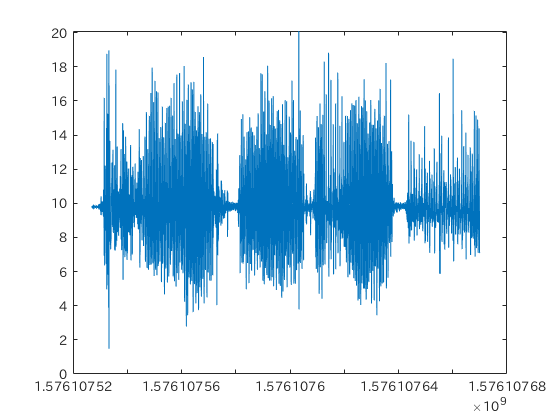

accel_g=generateAccelGround(msgs_android_imu);

plot(time_android_imu_actual,accel_g(:,3));

## High pass filter

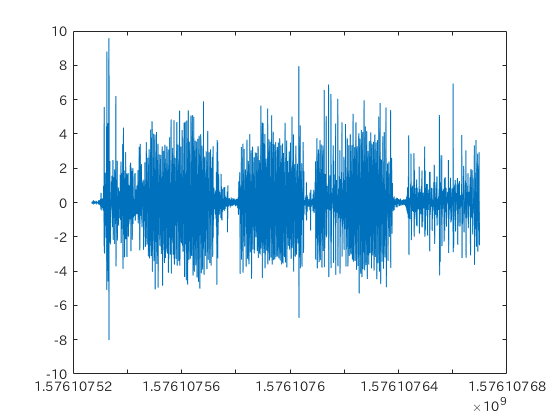

ALPHA=0.90;

accel_g_hpf=accelerationHighPassFilter(accel_g,ALPHA);

plot(time_android_imu_actual,accel_g_hpf(:,3));

## Low pass filter

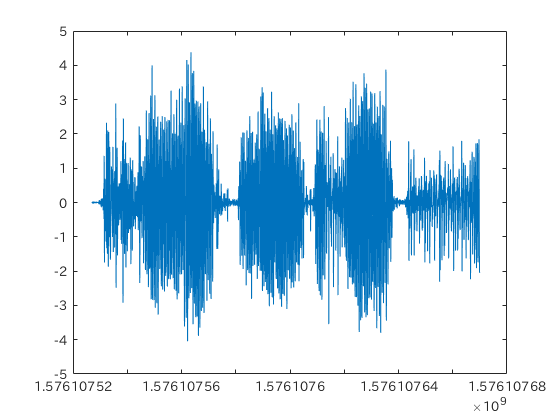

W=11;

accel_g_hpf_lpf=accelerationLowPassFilter(accel_g_hpf,W);

plot(time_android_imu_actual,accel_g_hpf_lpf(:,3));

## Step Detection

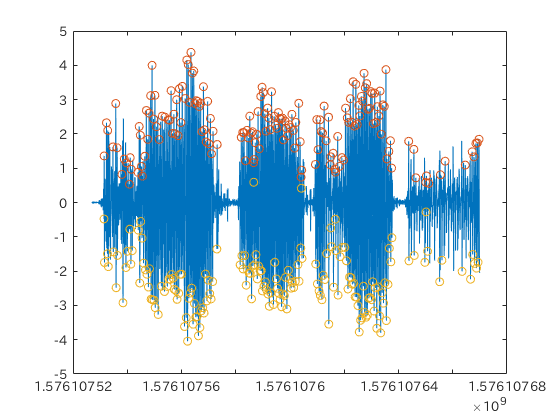

accel_g_filtered=accel_g_hpf_lpf;
N=30;
a_peak_th=0.5;
a_pp_th=0.4;
[boolean_step,boolean_peak,boolean_pp,boolean_slope,boolean_head]=...
    accelerationStepTimeDetector(accel_g_filtered,N,a_peak_th,a_pp_th);
time_step=time_android_imu_actual(boolean_step);
time_head=time_android_imu_actual(boolean_head);
accel_g_step=accel_g_filtered(boolean_step,:);
accel_g_head=accel_g_filtered(boolean_head,:);
plot(time_android_imu_actual,accel_g_hpf_lpf(:,3));
hold on
scatter(time_step,accel_g_step(:,3));
scatter(time_head,accel_g_head(:,3));
hold off

## P2P Calculation

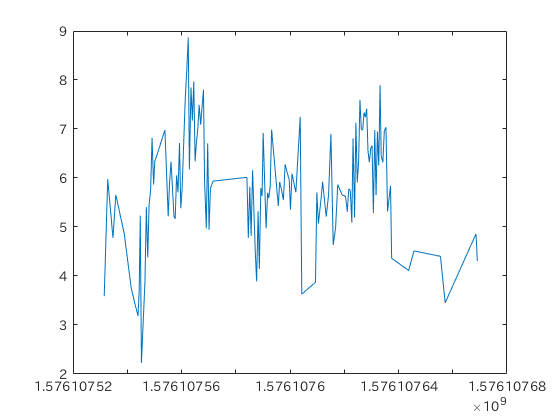

accel_g_p2p=accel_g_step-accel_g_head;
plot(time_step,accel_g_p2p(:,3));

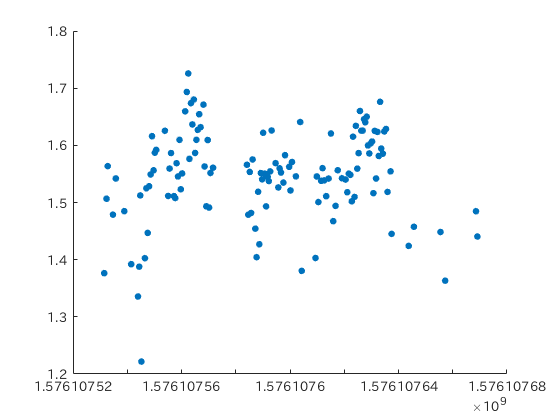

accel_g_p2p_4throot=nthroot(accel_g_p2p(:,3),4);
scatter(time_step,accel_g_p2p_4throot,25,'filled');